# Step-by-Step Tutorial for Calculating a Trajectory for Powered Flight

Aerodynamics is not just about calculating lift and drag for a body, but is used to compute the path of bodies and vehicles in flight, such as a spinning golf ball, a gliding airplane model, or an aircraft taking off from a run-way.

In this step-by-step tutorial, first we cover the basic concepts for calculating a trajectory of a body including aerodynamic forces.  Some basic MATLAB programming techniques are also covered for storing and plotting results.  Secondly we improve the trajectory model by accounting for contact with the ground, and then allowing for engine thrust.  Finally, we demonstrate how to calculate the take-off distance for an airplane on a runway!

## Section 1. Trajectory of Object in Air

In this section, let's go over some basic MATLAB programming techniques while computing the trajectory for an object traveling through the air subject to gravity and aerodynamic forces.

### Enter Parameters for the Problem

It is helpful to collect together all the parameters that define the problem, and to specify the units for each using the comments starting with "%"

We want to launch a ball or other object into the air at an initial $(X,Y)$ location, with velocity $V_x$, $V_y$. $Y$ is up and $X$ is to the right.  We need the mass of the object, the coefficients of lift and drag, and the properties of air.  We should also setup time parameters for the calculation, with a start time, an end time, and the number of time steps to calculate.

% Initial conditions
%  Initial position, (X, Y), in m.
xStart = 0.0;
yStart = 0.0;
%  Initial velocity, Vx, Vy, in m/s
VxStart = 5;
VyStart = 5;
launchAngleDeg = atan2d(VyStart,VxStart)

% Properties of object
%  Mass, in kg
mass = 1.0;
%  Reference area, in m^2.  For a ball this is typically the cross-sectional area, pi*R^2
area = 0.1;
%  Lift coefficient
CL = 0.0;
%  Drag coefficient
CD = 0.5;

% Properties of air and gravity
%  Density, rho, in kg/m^3
rho = 1.225;
%  Acceleration due to gravity, specified as a positive value, m^2/s
g = 9.81;

% Time parameters
%  Start time and end time, in sec, for the trajectory calculation
tStart = 0.0;
tEnd = 1.0;
%  Number of steps to calculate between start and end
numSteps = 100;

### Calculate the Trajectory

To calculate the trajectory, we will consider a free-body diagram for the body moving at $V_x$, $V_y$, including forces of gravity and aerodynamic lift and drag.  Let's keep $X$ as positive to the right and $Y$ as positive up.

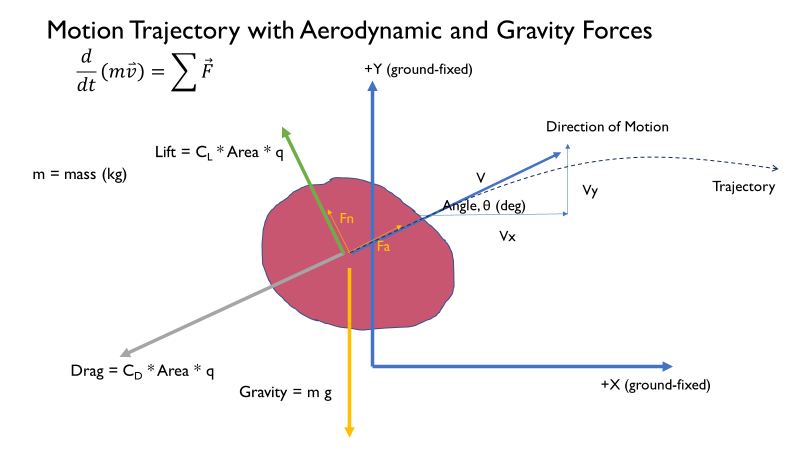

For this free-body diagram, we need to apply the gravity force in the vertical (minus $Y$) direction, while applying lift and drag forces relative to the direction of travel.  To do this, we will compute the **axial force** on the body from aerodynamics as equal to minus the drag force, as drag acts in the direction counter to the direction of motion.  For **normal force**, we compute the lift which is positive and normal to the direction of motion.   

#### Formulas for Forces Calculation


$$\begin{array}{l}
F_{\mathrm{axial}} =-C_D \;\;q\;S\\
F_{\mathrm{normal}} =C_L \;\;q\;S\\
F_x =F_{\mathrm{axial}} \;\cos \left(\theta \right)-F_{\mathrm{normal}} \;\sin \left(\theta \right)\\
F_y =F_{\mathrm{axial}} \;\sin \left(\theta \right)+F_{\mathrm{normal}} \;\cos \left(\theta \right)-m\;g\\
\mathrm{where}\;\mathrm{the}\;\mathrm{flight}\;\mathrm{angle},\theta ,\mathrm{is}\;\\
\theta =\tan^{-1} \frac{V_y }{V_x }
\end{array}$$


#### Trajectory Equations

The trajectory is calculated using Newton's second law, $\mathit{\mathbf{F}}=m\;\mathit{\mathbf{a}}$ , in the $X$ and $Y$ directions, and integrating to find the velocities and positions in time, namely:


$$\frac{\mathrm{d}}{\mathrm{d}t}V_x =\frac{F_x }{m}$$



$$\frac{\mathrm{d}}{\mathrm{d}t}V_y =\frac{F_y }{m}$$


#### Loop through Time-Steps to Integrate the Trajectory Equations

The following code sets the initial conditions and then uses a simple integration method in a loop over time steps.

% Calculate time step
dt = (tEnd - tStart)/numSteps;

% Set initial conditions
t = tStart;
X = xStart;
Y = yStart;
Vx = VxStart;
Vy = VyStart;

% Setup table to store the results so we can plot them later
results = array2table(zeros(numSteps+1,9),VariableNames=["t","X","Y","Vx","Vy","Ax","Ay","Fx","Fy"]);

Notes about [tables](https://www.mathworks.com/help/matlab/tables.html) in MATLAB.  Tables or arrays can be used to store results for plotting.  Tables are more general because you can specify the variable names for each column, and you can mix numeric and non-numeric data (like text or categories).  

- The two best functions to create a table are `array2table()`, and `table()`

- You can retrieve one column of the table as an array, by using dot indexing, like: `results.Vx`

- You can also extract a sub-table out of a table using `()` indexing, like `results(:,"Vx")`, which means all rows, but only the `"Vx"` column

- You can extract a numeric value or array out of a table using `{}` indexing, like `results{10,"Vx"}` which means the value in the tenth row, in the `"Vx"` column.

- You use the same notation as above when setting values into the table.  See below for how these functions and indexing are used

% Trajectory, loop in time
for i=1:numSteps+1

    % Axial Forces excluding gravity
    q = 0.5*rho*(Vx^2+Vy^2);
    FAxial = -CD*q*area;
    FNormal = CL*q*area;    

    % X,Y Forces including gravity
    % Calculate the flight angle, in deg, from the velocity
    flightAngle = atan2d(Vy,Vx);
    sinAng = sind(flightAngle);
    cosAng = cosd(flightAngle);
    % Calculate the contributions from axial forces
    Fx = FAxial*cosAng - FNormal*sinAng;
    Fy = FAxial*sinAng + FNormal*cosAng;
    % Add contributions from vertical force: gravity
    Fy = Fy - mass*g;    

    % Acceleration
    Ax = Fx/mass;
    Ay = Fy/mass;

Store the results in a table, prior to updating velocity and position:

    %  Note how we create a table with one row of results, then copy it
    %  into the "ith" row of the results table
    results(i,:) = table(t,X,Y,Vx,Vy,Ax,Ay,Fx,Fy);
    % Integrate to find the new velocity and position
    t = t + dt;
    Vx = Vx + dt*Ax;
    Vy = Vy + dt*Ay;
    X = X + dt*Vx;
    Y = Y + dt*Vy;
    
end

% Show the results table
results

### Plot the Trajectory and Forces vs. X

To easily visualize the trajectory and the calculated forces, plot $Y$ vs. $X$, then $F_x, F_y$ vs. $X$

% Plot the trajectory as Y vs. X
%  Set the size of the plot in pixels using the figure() function
figure("Position",[0 0 1000 300]);
plot(results.X,results.Y,LineWidth=2);
xlabel("X (m)");
ylabel("Y (m)");
xlim([xStart,X]);
title("Calculated Trajectory, Y vs. X")

Notes on plotting: the [`plot()`](https://www.mathworks.com/help/matlab/ref/plot.html) function takes 1D or 2D arrays for X and Y values as the first two arguments.  In MATLAB you can combine two arrays `A` and `B` side-by-side using `[A B]` or top-to-bottom using `[A; B]`.  After these two arguments, the `plot()` function takes optional arguments for plotting options, like `LineWidth=2`.  You add labels, limits, title and legend using additional functions as shown.

% Plot the forces
figure("Position",[0 0 1000 300]);
plot(results.X,[results.Fx results.Fy],LineWidth=2);
xlabel("X (m)");
ylabel("Fx,Fy (N)");
xlim([xStart,X]);
title("Calculated Forces vs. X")
legend(["Fx","Fy"]);

## Section 2. Add Force from the Ground

We would like to be able to consider the ground in our trajectories.  We can define the ground as $Y=0$, and not allow the body to travel below this value.  This will also help later when we want to compute trajectory for an airplane taking off and/or landing.

We simply add a force due to the ground, which counteracts non-positive $Y$ force, and we also limit the allowable vertical velocity when the object is in contact with the ground.  

### Compute Trajectory including Ground Reaction Force

#### Formulas for Forces Calculation including the Ground

The force balance is now:


$$\begin{array}{l}
F_{\mathrm{axial}} =-C_D \;\;q\;S\\
F_{\mathrm{normal}} =C_L \;\;q\;S\\
F_x =F_{\mathrm{axial}} \;\cos \left(\theta \right)-F_{\mathrm{normal}} \;\sin \left(\theta \right)\\
F_y =F_{\mathrm{axial}} \;\sin \left(\theta \right)+F_{\mathrm{normal}} \;\cos \left(\theta \right)-m\;g+F_{y,\mathrm{ground}} \\
\mathrm{where}\;\mathrm{the}\;\mathrm{ground}\;\mathrm{force}\;\mathrm{is}\;\mathrm{set}\;\mathrm{so}\;\mathrm{that}\;F_y \ge 0\;\mathrm{when}\;\mathrm{the}\;\mathrm{body}\;\mathrm{is}\;\mathrm{in}\;\mathrm{contact}\;\mathrm{with}\;\mathrm{the}\;\mathrm{ground},\mathrm{as}\;\mathrm{shown}\;\mathrm{below}\ldotp 
\end{array}$$


#### Adjust the Time Parameters

Let's create a longer time interval to see the object hit the ground.

%  Initial velocity, Vx, Vy, in m/s
VxStart = 5;
VyStart = 5;
launchAngleDeg = atan2d(VyStart,VxStart)

% Time parameters
%  Start time and end time, in sec
tStart = 0.0;
tEnd = 1.2;
%  Number of steps to calculate between start and end
numSteps = 120;

#### Calculate the Trajectory 

% Calculate time step
dt = (tEnd - tStart)/numSteps;

% Set initial conditions
t = tStart;
X = xStart;
Y = yStart;
Vx = VxStart;
Vy = VyStart;

% Setup table to store the results so we can plot them later
results = array2table(zeros(numSteps+1,9),VariableNames=["t","X","Y","Vx","Vy","Ax","Ay","Fx","Fy"]);

% Trajectory, loop in time
for i=1:numSteps+1

    % Axial Forces excluding gravity
    q = 0.5*rho*(Vx^2+Vy^2);
    FAxial = -CD*q*area;
    FNormal = CL*q*area;    

    % X,Y Forces including gravity
    % Calculate the flight angle, in deg, from the velocity
    flightAngle = atan2d(Vy,Vx);
    sinAng = sind(flightAngle);
    cosAng = cosd(flightAngle);
    % Calculate the contributions from axial forces
    Fx = FAxial*cosAng - FNormal*sinAng;
    Fy = FAxial*sinAng + FNormal*cosAng;
    % Add contributions from vertical forces: gravity and the ground
    Fy = Fy - mass*g;    
    if (Y<=0) % Detect that the body is in contact with the ground
        FyGround = max(0,-Fy); % The ground adds a force to oppose the net vertical force if it is negative
        Vy = max(0,Vy); % The vertical velocity cannot be negative if the body is in contact with the ground
        Fy = Fy + FyGround;
    end    

    % Acceleration
    Ax = Fx/mass;
    Ay = Fy/mass;

    % Store the results, prior to updating velocity and position
    %  Note how we create a table with one row of results, then copy it
    %  into the "ith" row of the results table
    results(i,:) = table(t,X,Y,Vx,Vy,Ax,Ay,Fx,Fy);

    % Integrate to find the new velocity and position
    t = t + dt;
    Vx = Vx + dt*Ax;
    Vy = Vy + dt*Ay;
    X = X + dt*Vx;
    Y = Y + dt*Vy;
    
end

% Show the results table
results

### Plot the Trajectory and Forces vs. X

% Plot the trajectory as Y vs. X
%  Set the size of the plot in pixels using the figure() function
figure("Position",[0 0 1000 300]);
plot(results.X,results.Y,LineWidth=2);
xlabel("X (m)");
ylabel("Y (m)");
xlim([xStart,X]);
title("Calculated Trajectory, Y vs. X")

% Plot the forces
figure("Position",[0 0 1000 300]);
plot(results.X,[results.Fx,results.Fy],LineWidth=2);
xlabel("X (m)");
ylabel("Fx,Fy (N)");
xlim([xStart,X]);
title("Calculated Forces vs. X")
legend(["Fx","Fy"],Location="northeast outside");

## Section 3. Add Thrust

Finally, by adding thrust as an axial force we can simulate powered flight including cruise, take-off and landing.  We add a fixed positive thrust value to the axial force as shown below.

### Calculate a Cruise Condition with Thrust

#### Formulas for Forces Calculation including Thrust, $T$

The force balance is now:


$$\begin{array}{l}
F_{\textrm{axial}} =T-C_D \;\;q\;S\\
F_{\textrm{normal}} =C_L \;\;q\;S\\
F_x =F_{\textrm{axial}} \;\cos \left(\theta \right)-F_{\textrm{normal}} \;\sin \left(\theta \right)\\
F_y =F_{\textrm{axial}} \;\sin \left(\theta \right)+F_{\textrm{normal}} \;\cos \left(\theta \right)-m\;g+F_{y,\textrm{ground}} \\
\textrm{where}\;\textrm{the}\;\textrm{ground}\;\textrm{force}\;\textrm{is}\;\textrm{set}\;\textrm{so}\;\textrm{that}\;F_y \ge 0\;\textrm{when}\;\textrm{the}\;\textrm{body}\;\textrm{is}\;\textrm{in}\;\textrm{contact}\;\textrm{with}\;\textrm{the}\;\textrm{ground}
\end{array}$$


#### Setup the Cruise Condition

Now let's consider a steady, level, cruise flight condition, in which the aircraft weight is balanced by lift, and the thrust exactly overcomes drag.  To compute the needed parameters, we select a cruise velocity of 10 m/s for a small model airplane with mass 1 kg.

% Set target cruise velocity, m/s
VCruise = 10.0;

% Properties of object
%  Mass, in kg
mass = 1.0;
%  Reference area, in m^2
area = 0.3;

% Compute the dynamic pressure at cruise
qCruise = 0.5*rho*VCruise^2;

% Compute the needed thrust, in N, to balance the axial drag force with an assumed drag coefficient
CD = 0.05;
T = CD*qCruise*area;
disp("Thrust at cruise is " + T + " N");

% Cruise lift coefficient to balance vehicle weight (solve equations above for CL in level flight)
CL = mass*g/(qCruise*area);
disp("CL at cruise should be: " + CL);

#### Initial Conditions and Time Steps

Let's assume a model plane cruising at altitude of 10 m with $X$-velocity of 10 m/s.  We can change the $Y$-velocity to see its effect on the trajectory.

% Initial conditions
%  Initial position, X, Y, in m.
xStart = 0.0;
yStart = 10.0;
%  Initial velocity, Vx, Vy, in m/s
VxStart = VCruise;
VyStart = 0.2;

% Time parameters
%  Start time and end time, in sec
tStart = 0.0;
tEnd = 1.0;
%  Number of steps to calculate between start and end
numSteps = 100;


#### Calculate the Trajectory 

% Calculate time step
dt = (tEnd - tStart)/numSteps;

% Set initial conditions
t = tStart;
X = xStart;
Y = yStart;
Vx = VxStart;
Vy = VyStart;

% Setup table to store the results so we can plot them later
results = array2table(zeros(numSteps+1,9),VariableNames=["t","X","Y","Vx","Vy","Ax","Ay","Fx","Fy"]);

% Trajectory, loop in time
for i=1:numSteps+1

    % Axial Forces excluding gravity
    q = 0.5*rho*(Vx^2+Vy^2);
    FAxial = T - CD*q*area;
    FNormal = CL*q*area;    

    % X,Y Forces including gravity
    % Calculate the flight angle, in deg, from the velocity
    flightAngle = atan2d(Vy,Vx);
    sinAng = sind(flightAngle);
    cosAng = cosd(flightAngle);
    % Calculate the contributions from axial forces
    Fx = FAxial*cosAng - FNormal*sinAng;
    Fy = FAxial*sinAng + FNormal*cosAng;
    % Add contributions from vertical forces: gravity and the ground
    Fy = Fy - mass*g;    
    if (Y<=0) % Detect that the body is in contact with the ground
        FyGround = max(0,-Fy); % The ground adds a force to oppose the net vertical force if it is negative
        Vy = max(0,Vy); % The vertical velocity cannot be negative if the body is in contact with the ground
        Fy = Fy + FyGround;
    end    

    % Acceleration
    Ax = Fx/mass;
    Ay = Fy/mass;

    % Store the results, prior to updating velocity and position
    %  Note how we create a table with one row of results, then copy it
    %  into the "ith" row of the results table
    results(i,:) = table(t,X,Y,Vx,Vy,Ax,Ay,Fx,Fy);

    % Integrate to find the new velocity and position
    t = t + dt;
    Vx = Vx + dt*Ax;
    Vy = Vy + dt*Ay;
    X = X + dt*Vx;
    Y = Y + dt*Vy;
    
end

% Show the results table
results

### Plot the Trajectory and Forces vs. X

% Plot the trajectory as Y vs. X
%  Set the size of the plot in pixels using the figure() function
figure("Position",[0 0 1000 300]);
plot(results.X,results.Y,LineWidth=2);
xlabel("X (m)");
ylabel("Y (m)");
xlim([xStart,X]);
title("Calculated Trajectory, Y vs. X")

% Plot the forces
figure("Position",[0 0 1000 300]);
plot(results.X,[results.Fx,results.Fy],LineWidth=2);
xlabel("X (m)");
ylabel("Fx,Fy (N)");
xlim([xStart,X]);
title("Calculated Forces vs. X")
legend(["Fx","Fy"],Location="northeast outside");

### Calculate Aircraft Take-Off

The same approach can be used to calculate a take-off trajectory for our model plane, but we normally need more lift and thrust to take off

#### Setup the Takeoff Condition

Choose a value of thrust and lift to takeoff within a reasonable distance

% Set a takeoff thrust value, in N
T = 2;

% Set a takeoff lift coefficient
CL = 1;

#### Initial Conditions and Time Steps

The aircraft begins stopped on the runway.

% Initial conditions
%  Initial position, X, Y, in m.
xStart = 0.0;
yStart = 0.0;
%  Initial velocity, Vx, Vy, in m/s
VxStart = 0.0;
VyStart = 0.0;

% Time parameters
%  Start time and end time, in sec
tStart = 0.0;
tEnd = 5.0;
%  Number of steps to calculate between start and end
numSteps = 100;


#### Calculate the Trajectory 

% Calculate time step
dt = (tEnd - tStart)/numSteps;

% Set initial conditions
t = tStart;
X = xStart;
Y = yStart;
Vx = VxStart;
Vy = VyStart;

% Setup table to store the results so we can plot them later
results = array2table(zeros(numSteps+1,9),VariableNames=["t","X","Y","Vx","Vy","Ax","Ay","Fx","Fy"]);

% Trajectory, loop in time
for i=1:numSteps+1

    % Axial Forces excluding gravity
    q = 0.5*rho*(Vx^2+Vy^2);
    FAxial = T - CD*q*area;
    FNormal = CL*q*area;    

    % X,Y Forces including gravity
    % Calculate the flight angle, in deg, from the velocity
    flightAngle = atan2d(Vy,Vx);
    sinAng = sind(flightAngle);
    cosAng = cosd(flightAngle);
    % Calculate the contributions from axial forces
    Fx = FAxial*cosAng - FNormal*sinAng;
    Fy = FAxial*sinAng + FNormal*cosAng;
    % Add contributions from vertical forces: gravity and the ground
    Fy = Fy - mass*g;    
    if (Y<=0) % Detect that the body is in contact with the ground
        FyGround = max(0,-Fy); % The ground adds a force to oppose the net vertical force if it is negative
        Vy = max(0,Vy); % The vertical velocity cannot be negative if the body is in contact with the ground
        Fy = Fy + FyGround;
    end    

    % Acceleration
    Ax = Fx/mass;
    Ay = Fy/mass;

    % Store the results, prior to updating velocity and position
    %  Note how we create a table with one row of results, then copy it
    %  into the "ith" row of the results table
    results(i,:) = table(t,X,Y,Vx,Vy,Ax,Ay,Fx,Fy);

    % Integrate to find the new velocity and position
    t = t + dt;
    Vx = Vx + dt*Ax;
    Vy = Vy + dt*Ay;
    X = X + dt*Vx;
    Y = Y + dt*Vy;
    
end

% Show the results table
results

### Plot the Trajectory and Forces vs. X

% Plot the trajectory as Y vs. X
%  Set the size of the plot in pixels using the figure() function
figure("Position",[0 0 1000 300]);
plot(results.X,results.Y,LineWidth=2);
xlabel("X (m)");
ylabel("Y (m)");
xlim([xStart,X]);
title("Calculated Trajectory, Y vs. X")

% Plot the forces
figure("Position",[0 0 1000 300]);
plot(results.X,[results.Fx,results.Fy],LineWidth=2);
xlabel("X (m)");
ylabel("Fx,Fy (N)");
xlim([xStart,X]);
title("Calculated Forces vs. X")
legend(["Fx","Fy"],Location="northeast outside");